Atividade 1

clear;
close all;
clc;

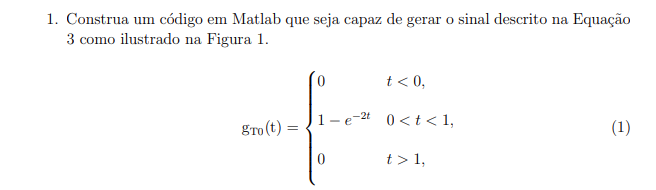

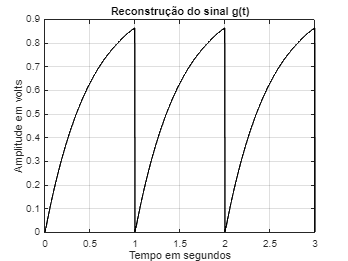

% Definindo parâmetros
% Período
T0 = 1; 
omega0 = 2 * pi / T0;

% Definindo o sinal g_T0(t)
t = linspace(0, 3, 1000);
g_T0 = zeros(size(t));

for k = 1:length(t)
    tk = mod(t(k), T0);
    if tk > 0 && tk <= 1
        g_T0(k) = 1 - exp(-2 * tk);
    end
end

% Construindo gráfico
figure;
plot(t, g_T0, 'k');
xlabel('Tempo em segundos');
ylabel('Amplitude em volts');
title('Reconstrução do sinal g(t)');
grid on;

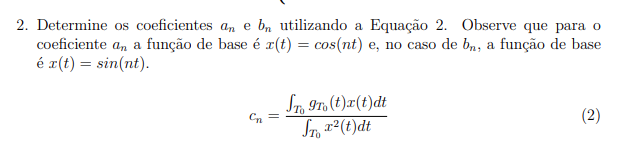

% Definindo parâmetros da Equação 2
T0 = 1; 
omega0 = 2 * pi / T0;

t = linspace(0, T0, 1000);

% Definindo o sinal g_T0(t) em um período
g_T0 = zeros(size(t));
for k = 1:length(t)
    if t(k) > 0 && t(k) <= 1
        g_T0(k) = 1 - exp(-2 * t(k));
    end
end

% Definindo funções base para os coeficientes
n = 1; 
xt_cos = cos(n * omega0 * t);
xt_sin = sin(n * omega0 * t);

% Calculando integrais
num_an = trapz(t, g_T0 .* xt_cos);
den_an = trapz(t, xt_cos.^2);
an = num_an / den_an;

num_bn = trapz(t, g_T0 .* xt_sin);
den_bn = trapz(t, xt_sin.^2);
bn = num_bn / den_bn;

%parâmetros
disp('Parâmetro an:'), disp(an);

Parâmetro an:
   -0.0795



disp('Parâmetro bn:'), disp(bn);

Parâmetro bn:
   -0.2499



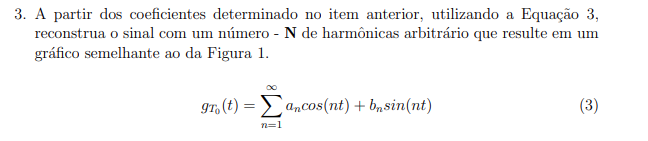

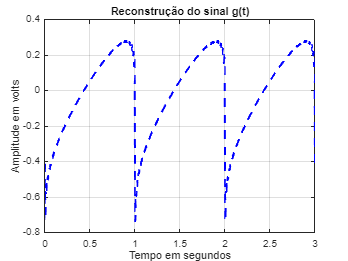

% Parâmetros ja obtidos de an e bnn:
an = -0.0795;
bn = -0.2499;
N = 100; 
T = 1; % Período do sinal
t = linspace(0, 3*T, 1000); % Tempo de 0 a 3 períodos

% Reconstrução do sinal
g_T = zeros(size(t)); % utilizando equação 3

for n = 1:N
    g_T = g_T + (an / n) * cos(n * 2 * pi * t / T) + (bn / n) * sin(n * 2 * pi * t / T);
end

% Construindo gráafico
figure;
plot(t, g_T, 'b--', 'LineWidth', 2);
xlabel('Tempo em segundos');
ylabel('Amplitude em volts');
title('Reconstrução do sinal g(t)');
grid on;

A partir da análise dos gráficos é possível perceber que o sinal sintetizado pela Equação 3 é parecido com o sinal original, mesmo com a discretização, que é comum em séries de Fourier com poucos termos.

% Parâmetros
T0 = 3;           % Período do sinal (em segundos)
fs = 1000;        
t = 0:1/fs:T0;    % tempo 0 a T0

%  sinal g_T0(t) ao longo de um período
gt0 = zeros(size(t));
for i = 1:length(t)
    if t(i) >= 0 && t(i) < 1
        gt0(i) = 1 - exp(-2*t(i)); % g_T0(t) = 1 - e^(-2t) para 0 < t < 1
    elseif t(i) >= 1 && t(i) < 2
        gt0(i) = 1 - exp(-2*(t(i)-1)); %% 1 < t < 2
    elseif t(i) >= 2 && t(i) < 3
        gt0(i) = 1 - exp(-2*(t(i)-2)); %%2 < t < 3
    else
        gt0(i) = 0; % Fora dos intervalos o sinal é zero
    end
end

% Cálculo da potência Equação 4

Pg = (1/T0) * trapz(t, gt0.^2); % Integração de g(t)^2 e divisão por T0

%%Resultado exercicio
fprintf('A potência total do sinal gT0(t) de aprox ~~ %f watts\n', Pg);

A potência total do sinal gT0(t) é: 0.380383 watts
